# Lab 7 & 8

## Kurt Delegard

## PHYS 434 AB

### Time spent drafting: 15+ hours

In this lab we would like to identify and isolate the signals that HERA searches for. The signal from the sky is known to be very steady in time, as opposed to the background contamination which can vary based on the time of day or rotation of the Earth.

clear;
clc;

load('hera_data.mat')
%Use just XX polarized light, as it has the highest magnitude of visibility
pol = 1;
range = 1:1378;
%Make an array of complex numbers from the visdata struct
visdata_re = visdata.r(pol, :, 1, :);
visdata_im = visdata.i(pol, :, 1, :);
visdata_complex = complex(visdata_re, visdata_im);

visdata_mag = abs(visdata_complex);
visdata_time1 = visdata_mag(:, :, 1, range);

We are given data from all 1,378 baselines for 60 instances in time, which is represented by a vector of length 1,378 * 60 (where every 1,378 entries represents a diferent value of time). Again, time is given in units of Julian days, which is shown [here](http://reionization.org/manual_uploads/HERA069_IDR2.2_Memo_v2.html). The time t=1 corresponds to the first entry in time_array, and is the time which corresponds to the first 1,378 entries in the [baseline pairs * times] column of the array visdata:

time_1 = time_array(1);
fprintf('%.6f\n', time_1)

2458108.125574


By plotting the complex magnitude of the visibility of the first 1,378 baselines in this vector against frequency, we can create a plot which shows the readings of all baselines at time t = 1:

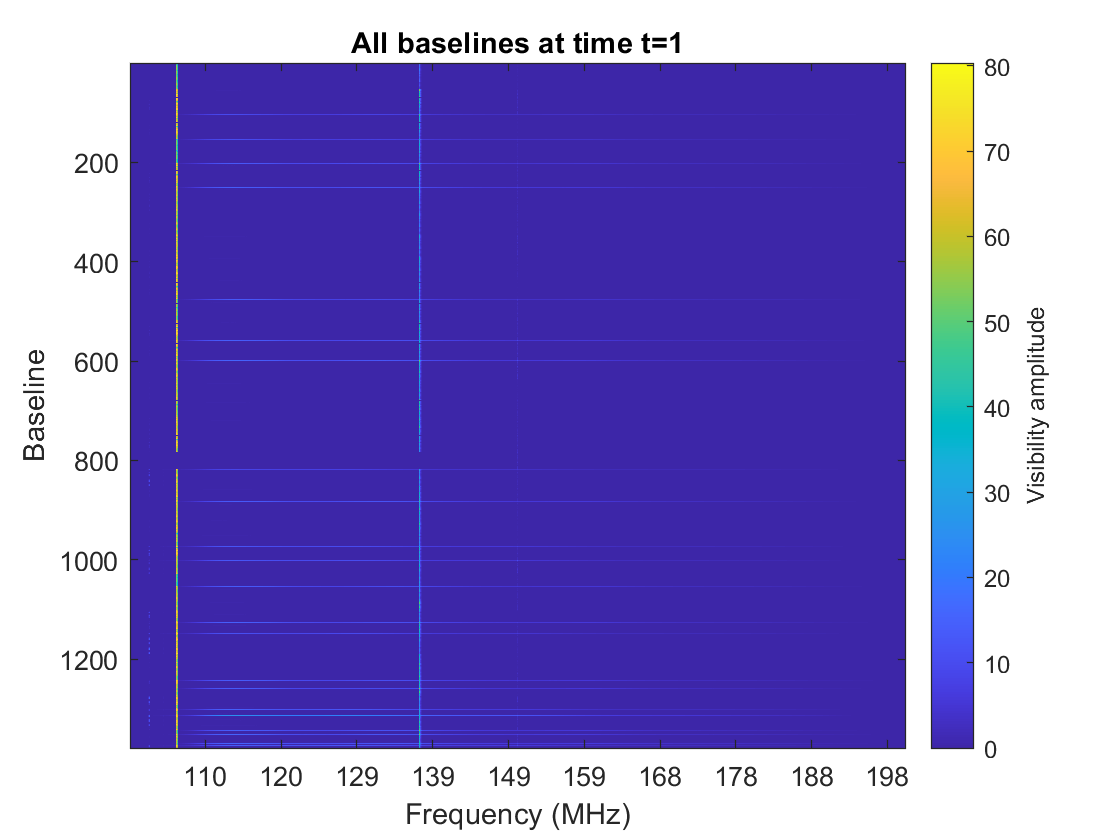

%Plot the raw data for time 1
clf;
imagesc(squeeze(visdata_time1)')
xt = get(gca, 'XTick');
set(gca, 'XTick', xt, 'XTickLabel', round(xt/10.24 + 100));
xlabel('Frequency (MHz)');
ylabel('Baseline')
c = colorbar;
c.Label.String = "Visibility amplitude";
title('All baselines at time t=1')

We can remove these horizontal streaks of data, which correspond to baselines comprised of one antenna being correlated with itself. To do this, we simply remove all data with indices corresponding to baselines with the same antenna paired with itself.

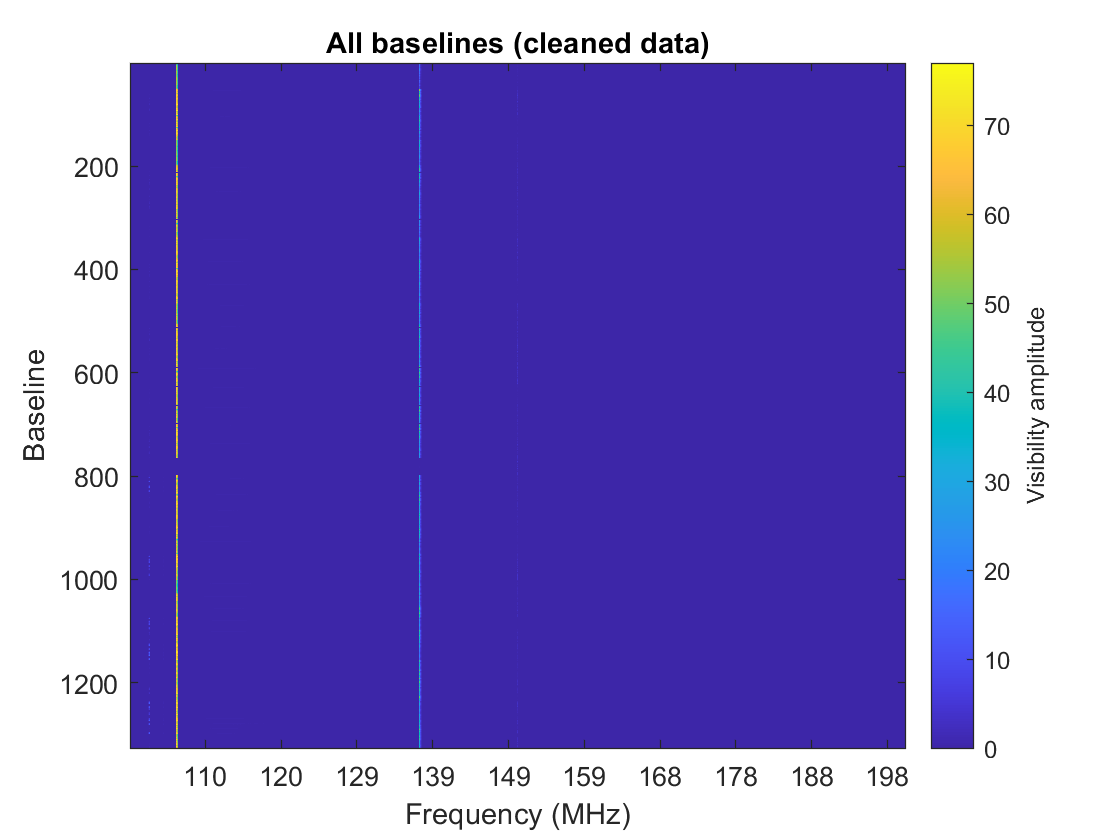

commonpair_indices = baselines(:, 1) == baselines(:, 2);
clean_data = visdata_time1(:, :, :, ~commonpair_indices);
clean_img = squeeze(clean_data)';
clf;
imagesc(clean_img);
xt = get(gca, 'XTick');
set(gca, 'XTick', xt, 'XTickLabel', round(xt/10.24 + 100));
xlabel('Frequency (MHz)');
ylabel('Baseline')
c = colorbar;
c.Label.String = "Visibility amplitude";
title('All baselines (cleaned data)')

We can observe the different frequencies at which some sort of appreciable data is recieved by the array by plotting the sum of the visibility amplitudes across all these baselines versus the range of frequencies:

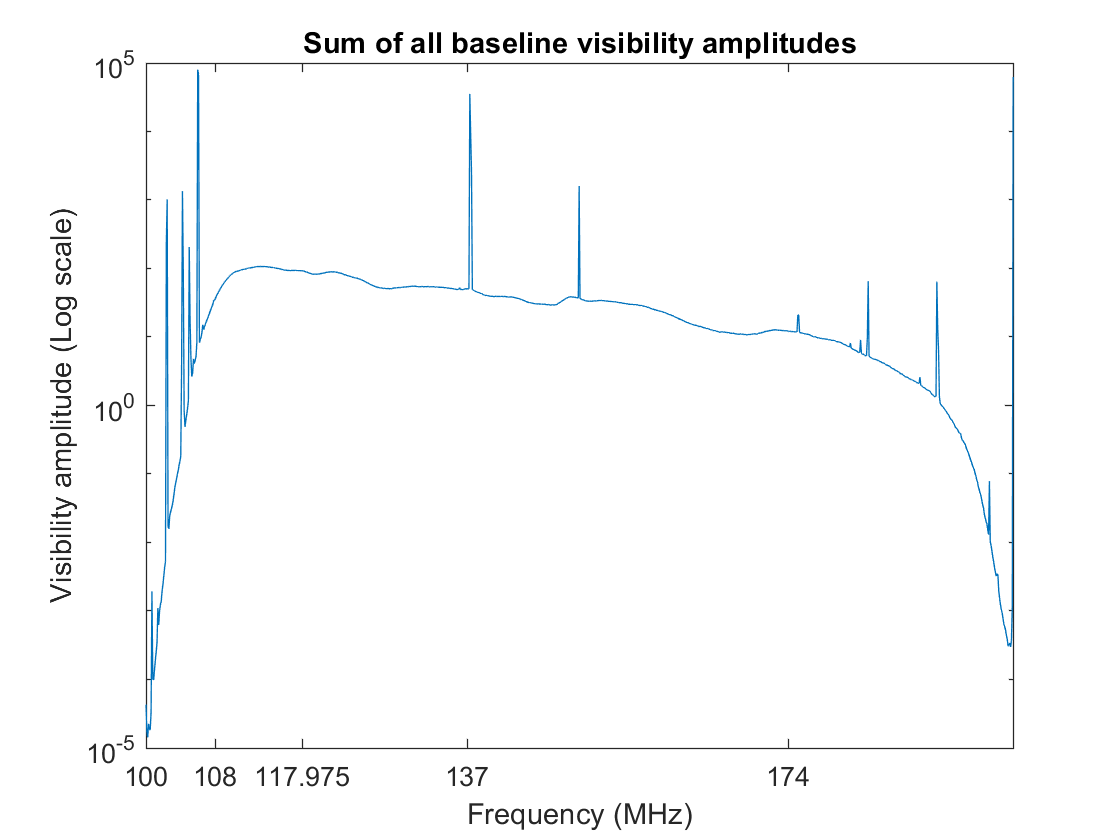

amplitude_all = sum(clean_img, 1);
clf;
semilogy(freq_array ./ 1e6, amplitude_all(1:1024))
xticks([100 108 117.975 137 174])
xlabel('Frequency (MHz)');
ylabel('Visibility amplitude (Log scale)')
title(['Sum of all baseline visibility amplitudes'])

From this plot, we can also observe some anomalous data patterns at the high and low ends of the frequency spectrum. These patterns imply that the visibility amplitude drops significantly at frequencies $f<~110\;\textrm{MHz}$ and $f>~180\;\textrm{MHz}$. This may be due to the radio frequency allocation in South Africa: frequencies less than 108 MHz and greater than 174 MHz are primarily used for broadcasting, which we may assume to correspond to radio or television broadcasting from sources at ground level. On the other hand, frequencies that are within this range of values are primarily used for aeronautical and satellite communication with the Earth. Since the HERA antennas are aimed up at the sky, the background is likely more influenced by electromagnetic radiation from above rather than from sources on the ground, such as television and radio broadcating antennas.

Here is a section of the South African frequency allocation chart overlaid on the plot above.

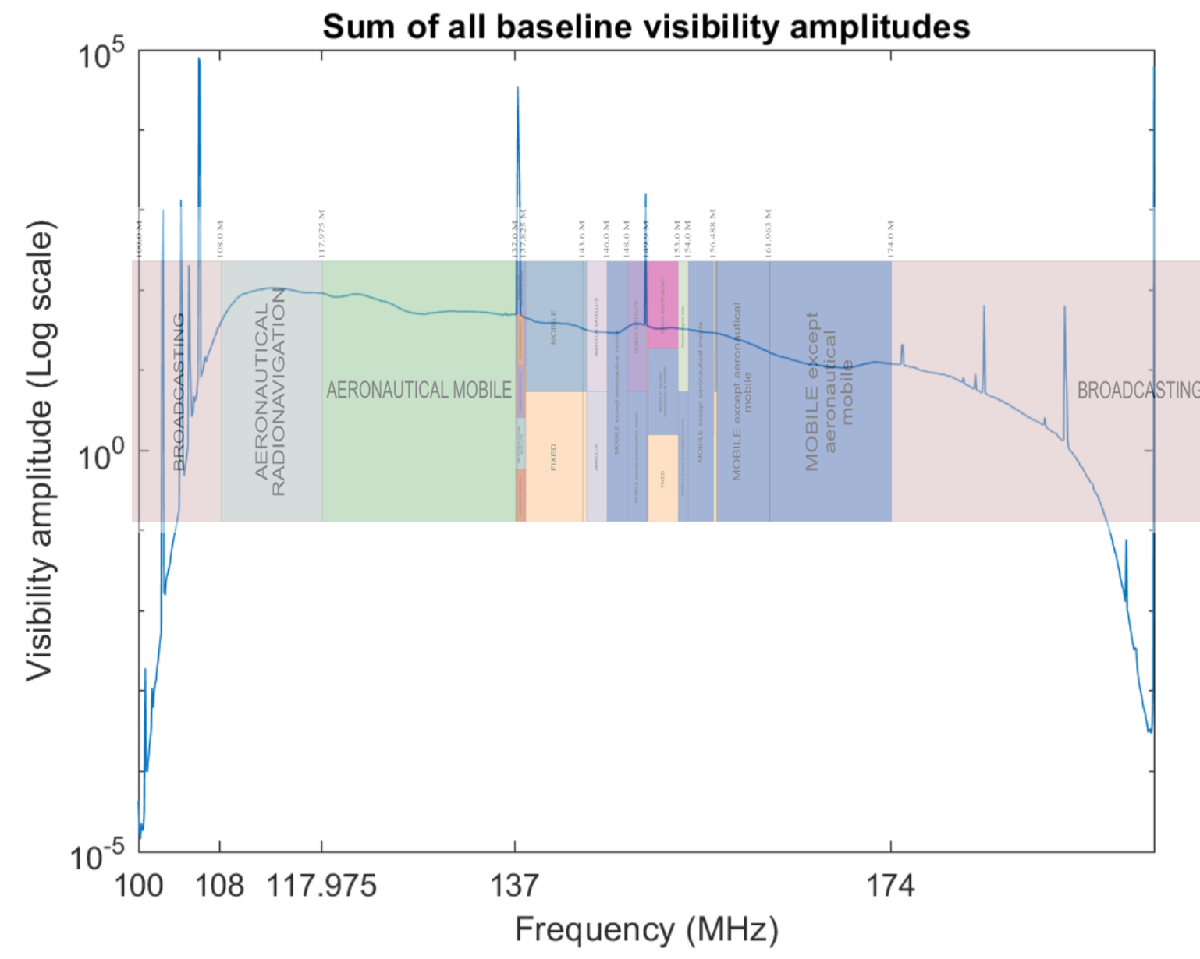

From this plot we can infer the most likely sources of background:

- Several spikes in the low-frequency range (<108 MHz) are from broadcasting sources, which likely correspond to TV or radio stations.

- The allocation at ~137 MHz is hard to see, but frequencies in this region are used for space operations and research, as well as meteorological and mobile satellites.

- The spike near ~150 MHz is allocated for radionavigation and mobile satellites.

- Spikes past 174 MHz once again correspond to broadcasting.

Now we would like to observe the data recieved by a single baseline over several instances of time.

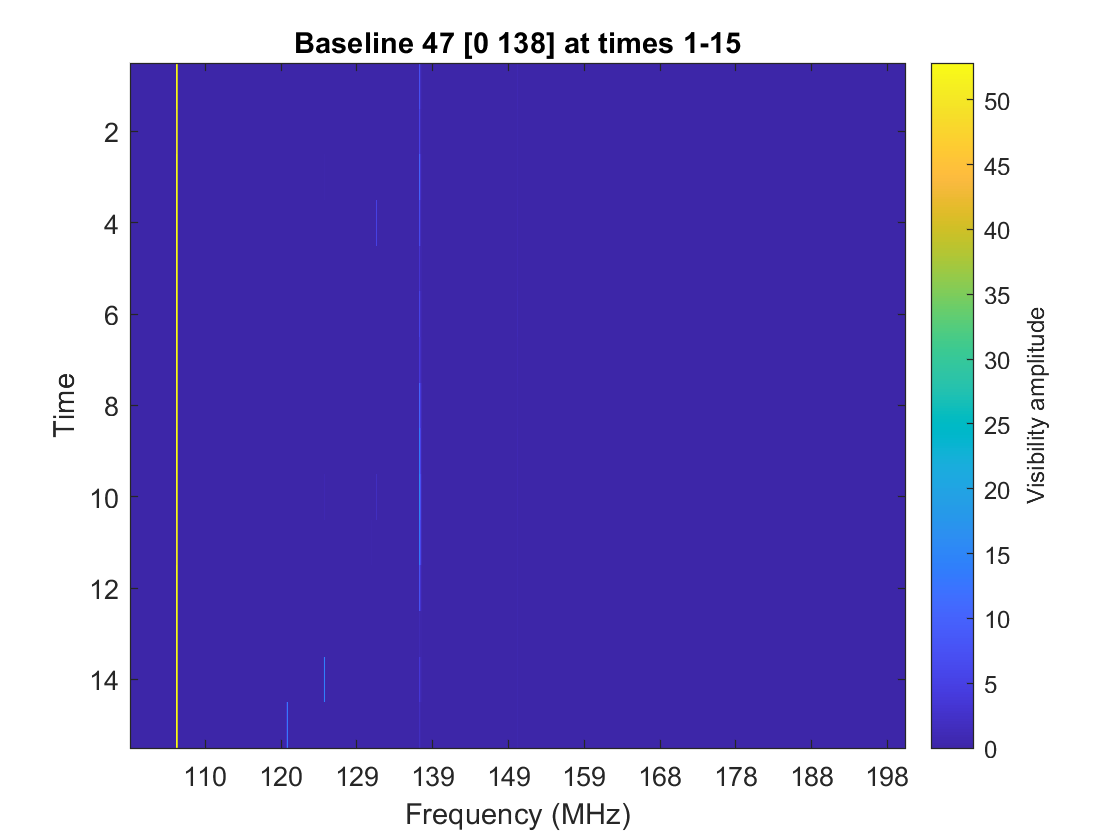

%Choose a random baseline
baseline = 47;
antennas = baselines(baseline, :);

baseline_waterfall_data = visdata_mag(:, :, :, baseline:1378:end);
waterfall_img = squeeze(baseline_waterfall_data)';

clf;
imagesc(waterfall_img);
xt = get(gca, 'XTick');
set(gca, 'XTick', xt, 'XTickLabel', round(xt/10.24 + 100));
xlabel('Frequency (MHz)');
yticks('auto');
ylabel('Time');
c = colorbar;
c.Label.String = "Visibility amplitude";
title(['Baseline ' num2str(baseline) ' ' mat2str(antennas) ' at times 1-15']);

The signal from this baseline looks like it varies in time. Short spikes of visibility appear in the 120-130 MHz range from t=14 to t=15, and the signal at ~137 MHz seems to decrease in intensity over time, possibly due to the relative movement of HERA to various satellites. We expect that the signals HERA is searching for (usually signals from distant radio galaxies) are very steady in time, remaining stable over millions of years, so these patterns are likely sources of background, not the signal HERA is searching for.

For this particular baseline, we can also plot the visibility magnitude summed over time; 15 time intervals, to be exact.

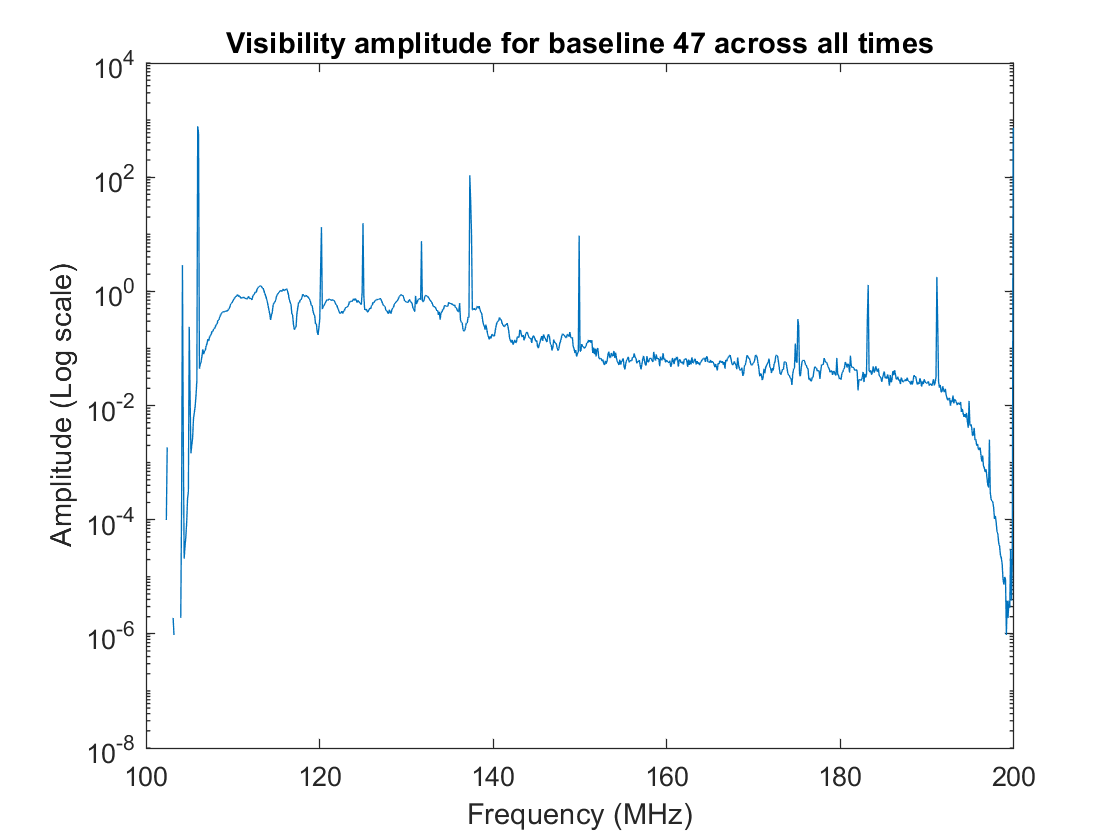

amplitude1 = sum(waterfall_img, 1);
clf;
semilogy(freq_array ./ 1e6, amplitude1(1:1024))
xlabel('Frequency (MHz)');
ylabel('Amplitude (Log scale)')
title(['Visibility amplitude for baseline ' num2str(baseline) ' across all times'])

We can tell that the large spikes in this plot correspond to the bright streaks we see in the waterfall plot. However, the noisy line which can be seen in regions absent of spikes corresponds to the background across this region. This background, which seems to vary wildly based on small changes in frequency, may prove to make our analysis of this data harder.

We can get a glimpse of this by plotting a histogram of the visibility data with bins of different frequencies. As stated earlier, the data exhibits some anomalous behavior near the edges of the frequency range, so we will only plot the middle 600 indices of the frequency range, corresponding to the range $119\ldotp 43\;\textrm{MHz}<f<178\ldotp 03\;\textrm{MHz}$. Furthermore, we will only plot visibilities of amplitude less than 0.1; this corresponds to the random background, excluding the strong background sources which we can single out.

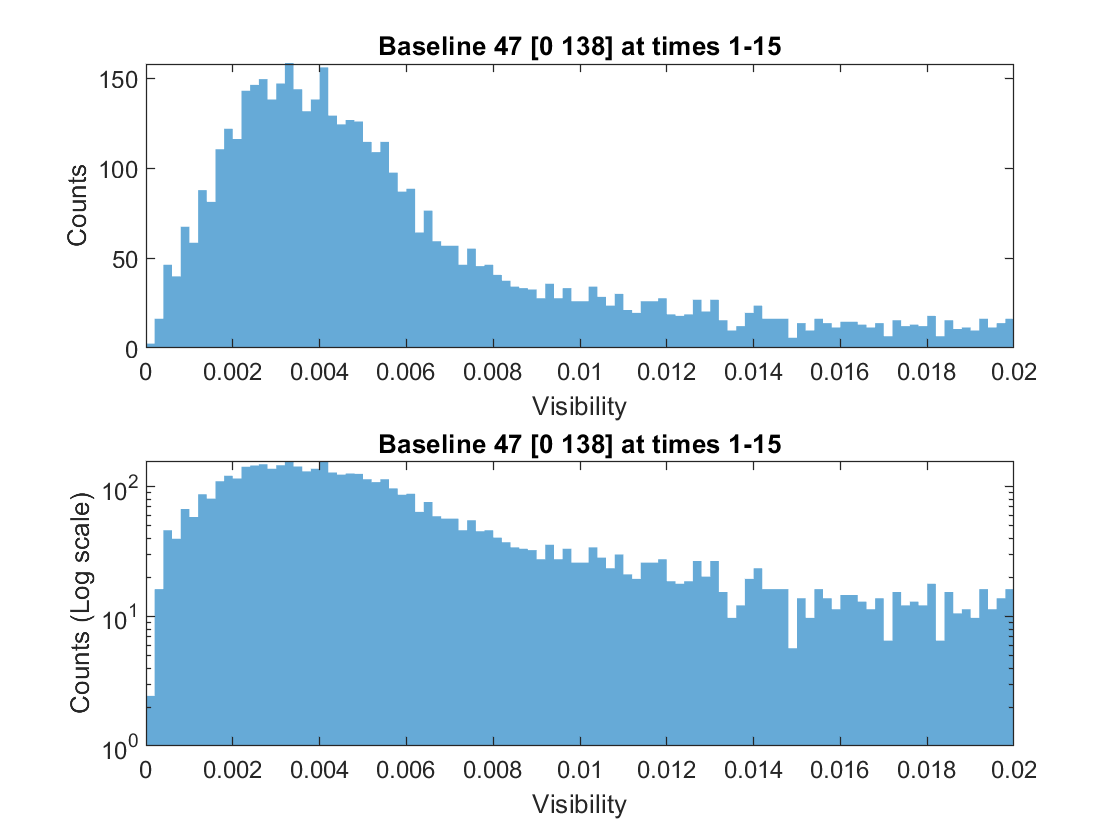

clf;
nbins = 100;
waterfall_img_limit = waterfall_img(:, 200:800);
maxval = 0.02;


subplot(2, 1, 1)
histogram(waterfall_img_limit(waterfall_img_limit < maxval), nbins, 'EdgeColor', 'none', 'Normalization', 'pdf'), hold on;
xlabel('Visibility');
ylabel('Counts');
xlim([0 maxval])
title(['Baseline ' num2str(baseline) ' ' mat2str(antennas) ' at times 1-15']);

subplot(2, 1, 2)
histogram(waterfall_img_limit(waterfall_img_limit < maxval), nbins, 'EdgeColor', 'none', 'Normalization', 'pdf'), hold on;
set(gca, 'YScale', 'log')
xlabel('Visibility');
ylabel('Counts (Log scale)');
xlim([0 maxval])
title(['Baseline ' num2str(baseline) ' ' mat2str(antennas) ' at times 1-15']);

This distribution, while noisy, seems to follow an approximately lognormal trend. 

Perhaps an ideal candidate to look at would be a baseline with a background that remains relatively constant across all frequencies, i.e. a background with very little variation. We can find which baseline has the smallest variation in its background by finding the standard deviation of each baseline's visibility data between $119\ldotp 43\;\textrm{MHz}<f<178\ldotp 03\;\textrm{MHz}$ as stated above, and then choosing the baseline with the smallest background variation.

%This is the range of the middle 600 indices
freq_array([200, 800])

ans = 	1.0e+08 *

    1.1943
    1.7803


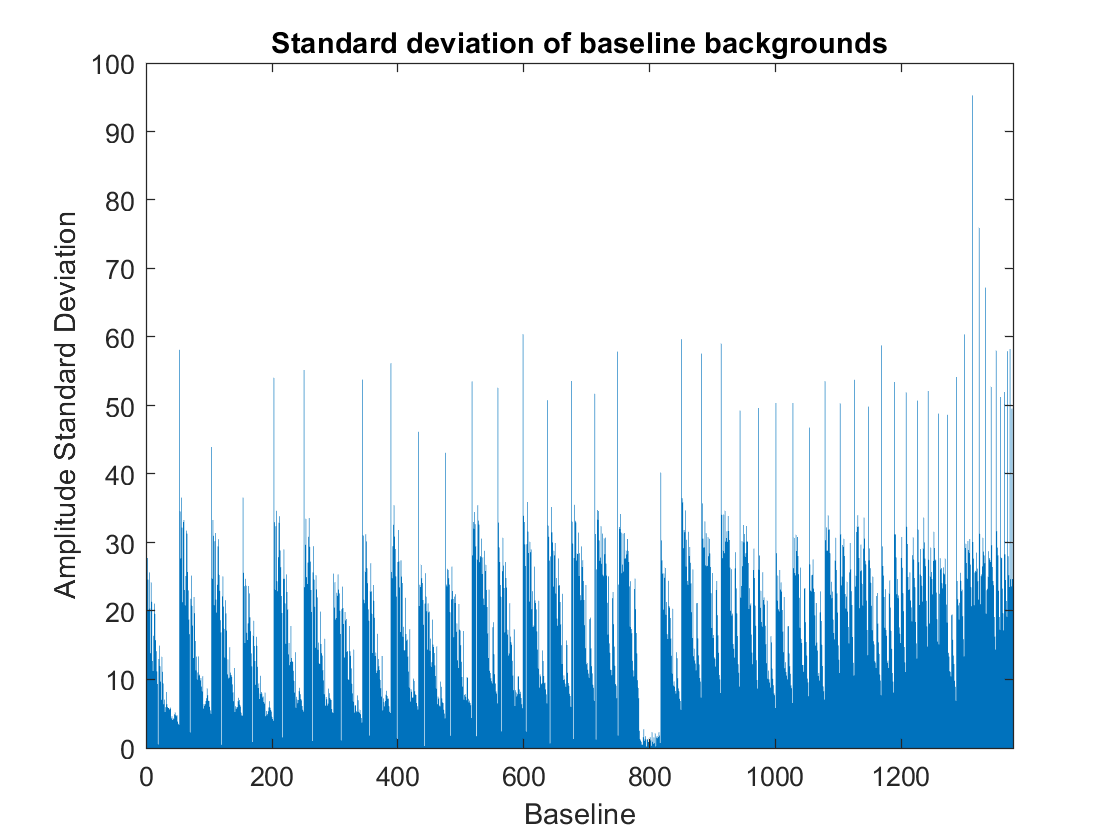

devs = zeros(1, 1378);
for ii = 1:1378
    antennas = baselines(ii, :);
    waterfall_data = visdata_mag(:, :, :, ii:1378:end);
    water_img = squeeze(waterfall_data)';
    amp = sum(water_img, 1);
    devs(ii) = std(amp(200:800));
end
clf;
bar(1:1378, devs, 1)
xlabel('Baseline')
ylabel('Amplitude Standard Deviation')
title('Standard deviation of baseline backgrounds')

%Baseline with the smallest bkg standard deviation
[~, baseline] = min(devs)

baseline = 795

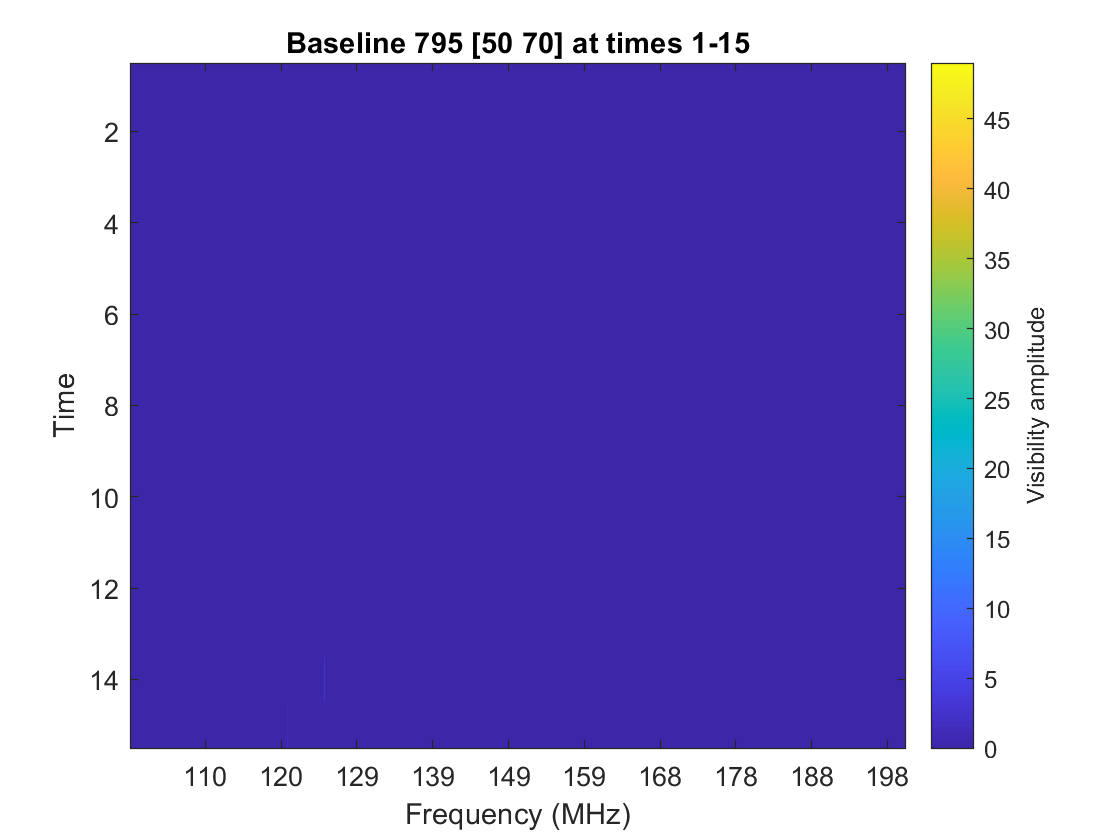

antennas = baselines(baseline, :);

baseline_waterfall_data = visdata_mag(:, :, :, baseline:1378:end);
waterfall_img = squeeze(baseline_waterfall_data)';

clf;
imagesc(waterfall_img);
xt = get(gca, 'XTick');
set(gca, 'XTick', xt, 'XTickLabel', round(xt/10.24 + 100));
xlabel('Frequency (MHz)');
yticks('auto');
ylabel('Time');
c = colorbar;
c.Label.String = "Visibility amplitude";
title(['Baseline ' num2str(baseline) ' ' mat2str(antennas) ' at times 1-15']);

It is hard to discern anything in this image due to the low variation in the observed signal.

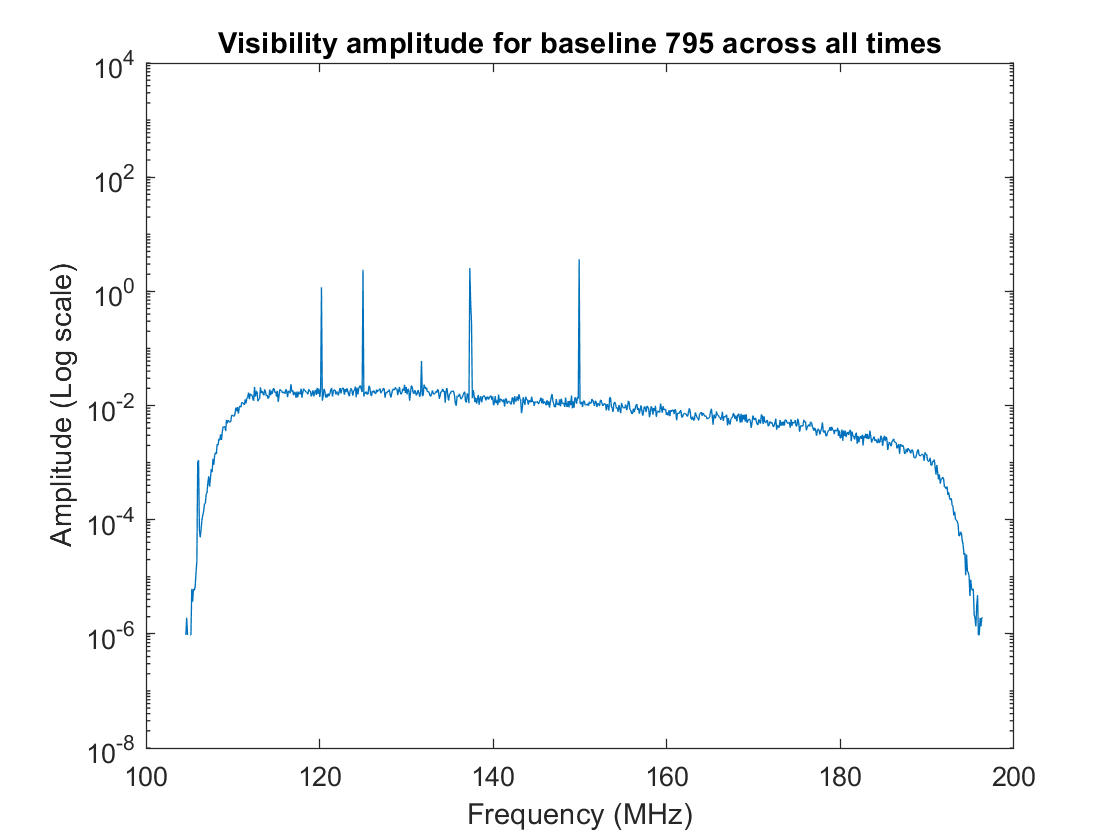

amplitude1 = sum(waterfall_img, 1);
clf;
semilogy(freq_array ./ 1e6, amplitude1(1:1024))
xlabel('Frequency (MHz)');
ylabel('Amplitude (Log scale)')
title(['Visibility amplitude for baseline ' num2str(baseline) ' across all times'])

Here we can see that the background is much less noisy than the previous single baseline.

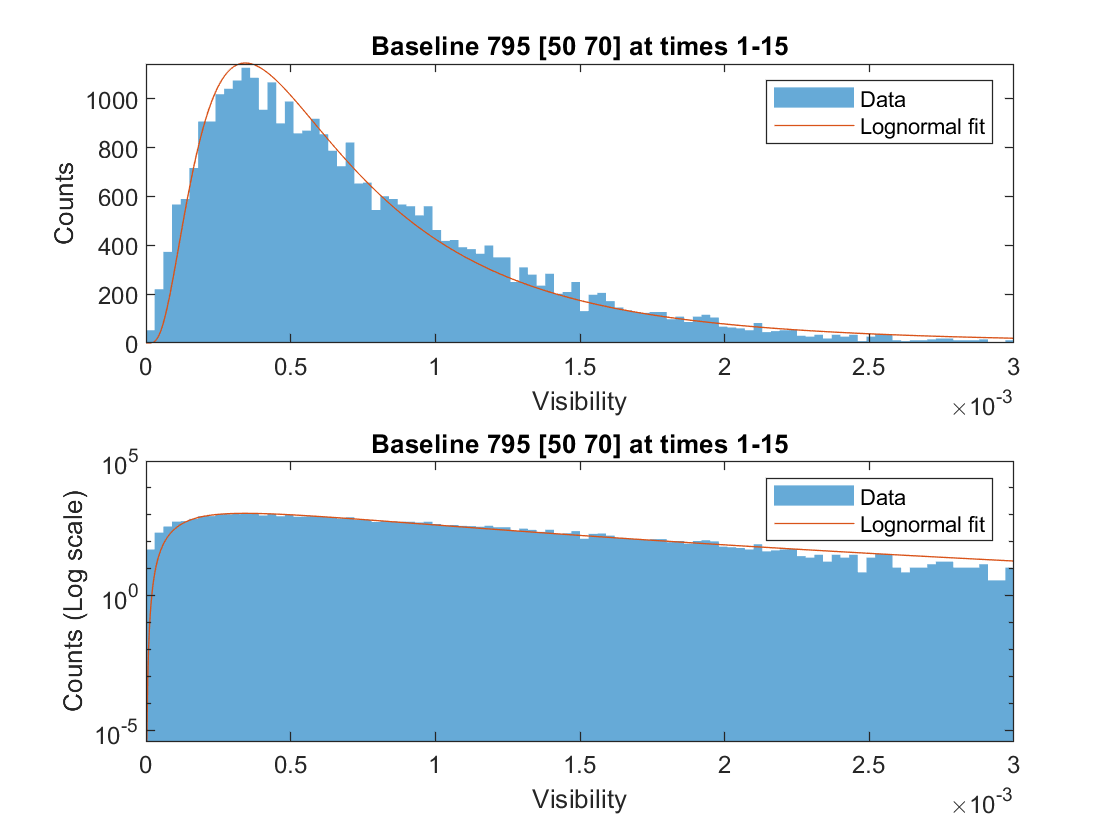

clf;
nbins = 100;
waterfall_img_limit = waterfall_img(:, 200:800);
maxval = 0.003;

subplot(2, 1, 1)
histogram(waterfall_img_limit(waterfall_img_limit < maxval), nbins, 'EdgeColor', 'none', 'Normalization', 'pdf'), hold on;
xs = linspace(0, maxval, 1000);
ys = lognpdf(xs, -7.4, 0.76);

plot(xs, ys);

xlabel('Visibility');
ylabel('Counts');
xlim([0 maxval])
title(['Baseline ' num2str(baseline) ' ' mat2str(antennas) ' at times 1-15']);
legend('Data', 'Lognormal fit');
subplot(2, 1, 2)
histogram(waterfall_img_limit(waterfall_img_limit < maxval), nbins, 'EdgeColor', 'none', 'Normalization', 'pdf'), hold on;

plot(xs, ys);

set(gca, 'YScale', 'log')
xlabel('Visibility');
ylabel('Counts (Log scale)');
xlim([0 maxval])
title(['Baseline ' num2str(baseline) ' ' mat2str(antennas) ' at times 1-15']);
legend('Data', 'Lognormal fit');

Again, this histogram looks much less noisy than that of the previous baseline we looked at.

Since the signal from the sky is very constant over time, this signal should appear in the data from every baseline. Therefore, by subtracting the data from a single baseline between two neighboring points in time, we should be able to remove the sky signal from our data. What we will be left with, then, is the background. We can take the average of each of these differences to gain a better representation of the background among all baselines.

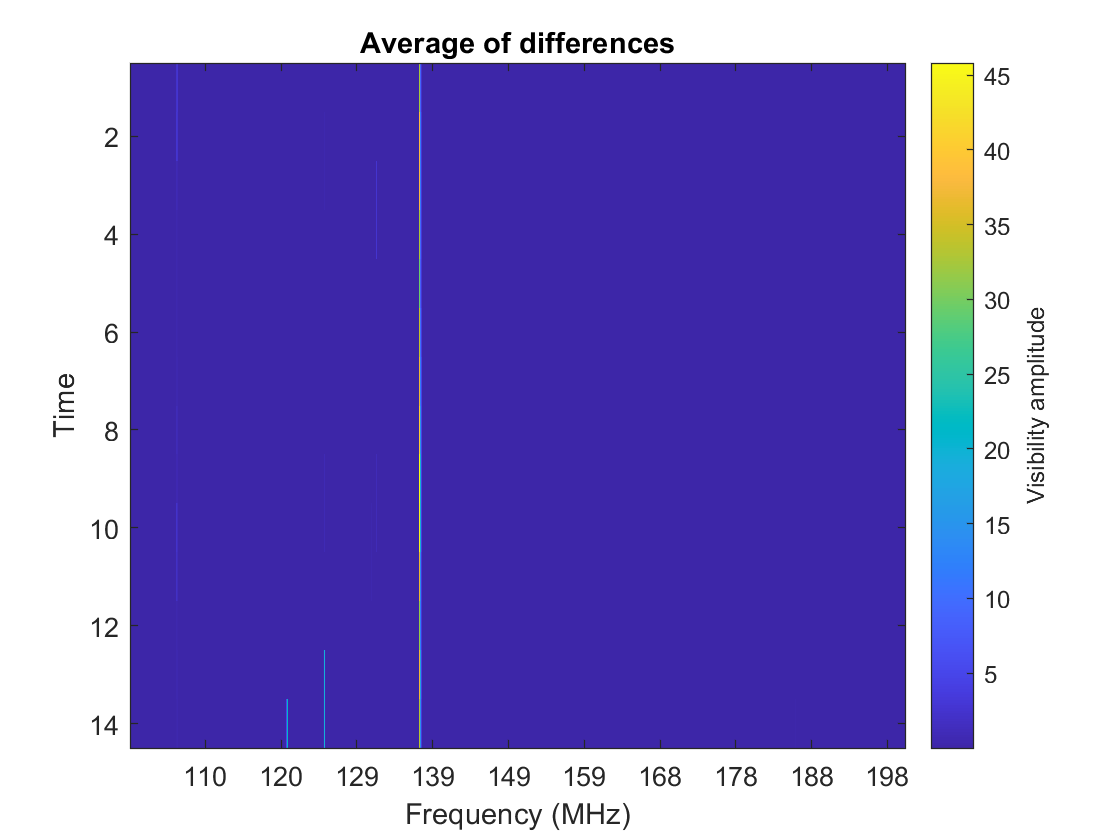

vis = squeeze(visdata_complex);

%Differenced times for time 1

diffs = zeros(1024, 14, 1378);
for ii = 1:1378
    diffs(:, :, ii) = diff(vis(:, ii:1378:end), 1, 2);
end

%remove vaa from data
clean_diffs = abs(diffs(:, :, ~commonpair_indices));

averages = mean(abs(clean_diffs), 3);
clf;
imagesc(averages');
xt = get(gca, 'XTick');
set(gca, 'XTick', xt, 'XTickLabel', round(xt/10.24 + 100));
xlabel('Frequency (MHz)');
yticks('auto');
ylabel('Time');
c = colorbar;
c.Label.String = "Visibility amplitude";
title('Average of differences');

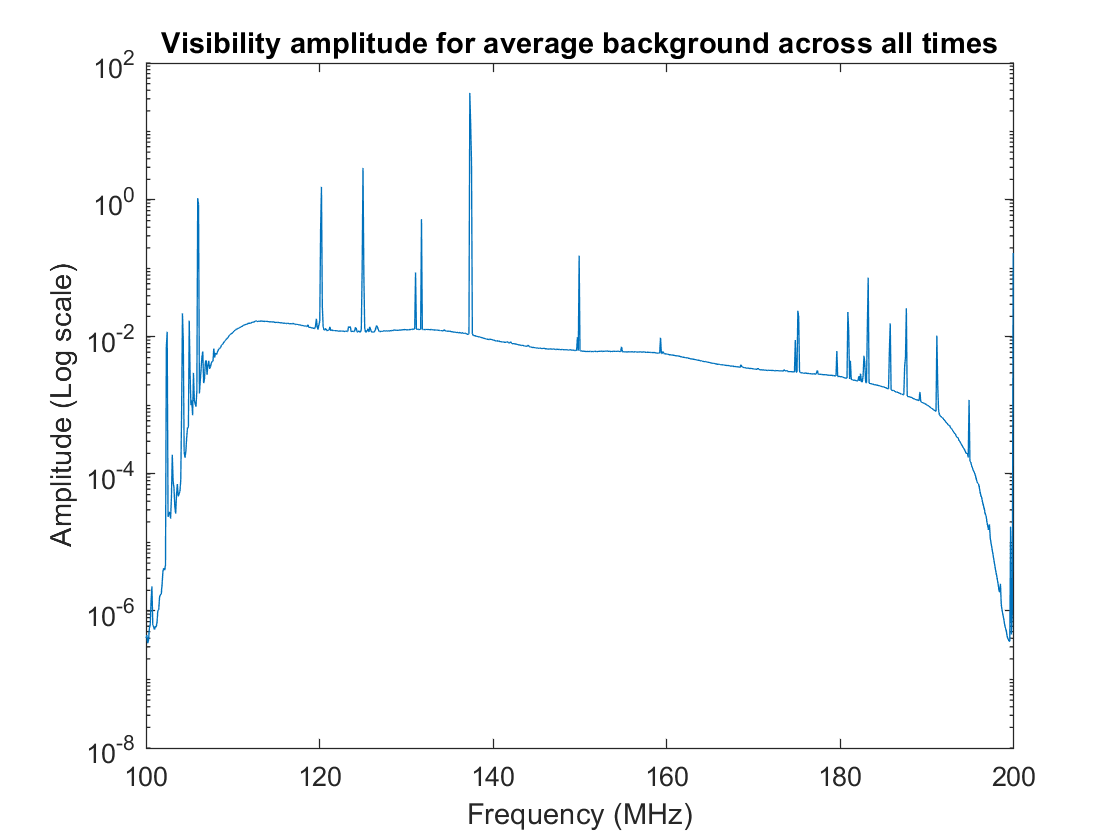

amplitude_avg = mean(averages, 2);
clf;
semilogy(freq_array ./ 1e6, amplitude_avg(1:1024))
xlabel('Frequency (MHz)');
ylabel('Amplitude (Log scale)')
title(['Visibility amplitude for average background across all times'])

We can histogram the average of this data to find its distribution:

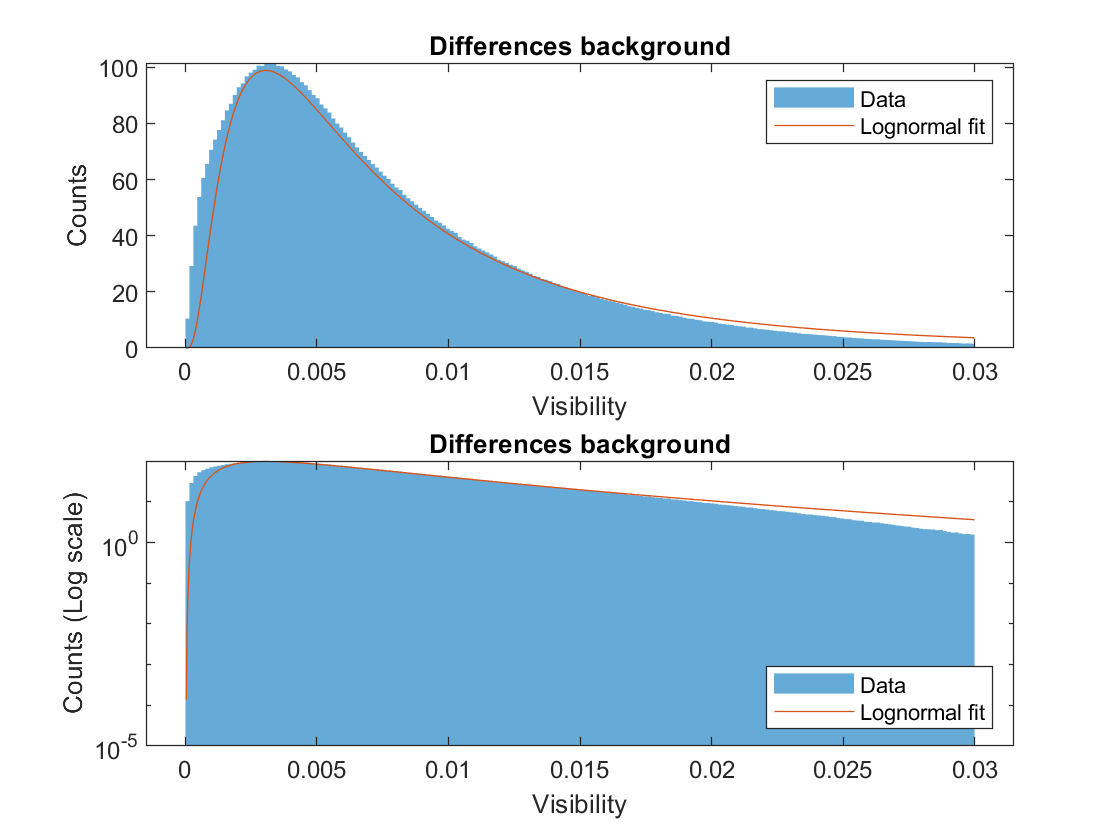

%Average per frequency
clf;
nbins = 200;
maxval = 0.03;
clean_diffs_lim = clean_diffs(200:800, :, :);
cl = clean_diffs_lim(clean_diffs_lim < maxval);

subplot(2, 1, 1)
histogram(cl, nbins, 'EdgeColor', 'none', 'Normalization', 'pdf'), hold on;

%PD = fitdist(reshape(cl, [], 1), 'Lognormal')
xs = linspace(0, maxval, 1000);
ys = lognpdf(xs, -5, 0.89);

plot(xs, ys)
xlabel('Visibility');
ylabel('Counts');
title('Differences background')
legend('Data', 'Lognormal fit');

subplot(2, 1, 2)
histogram(cl, nbins, 'EdgeColor', 'none', 'Normalization', 'pdf'), hold on;

plot(xs, ys)
set(gca, 'YScale', 'log')
xlabel('Visibility');
ylabel('Counts (Log scale)');
title('Differences background')
legend('Data', 'Lognormal fit', 'location', 'southeast');

This data is much more smoothly distributed.

By plotting the average of the differences, we can observe even more patterns in the data

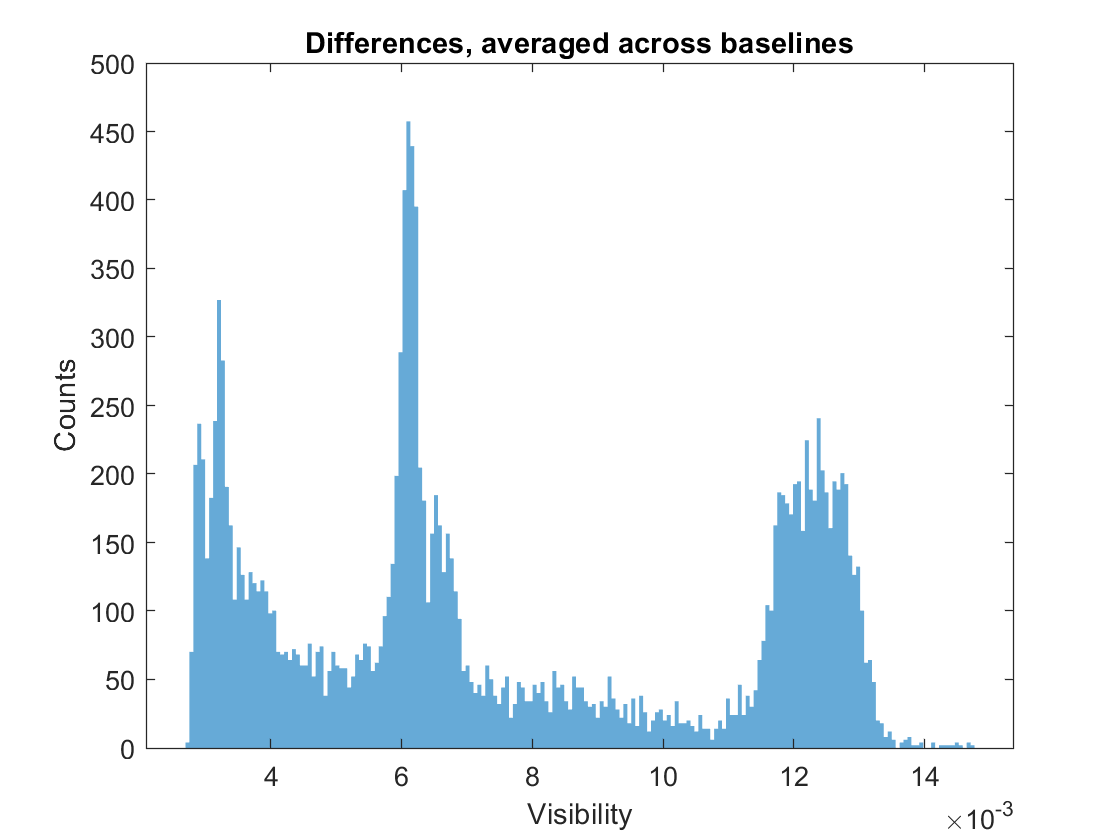

maxval = 0.015;
clf;
clean_diffs_avg = mean(clean_diffs(200:800, :, :), 3);
cl = clean_diffs_avg(clean_diffs_avg < maxval);
histogram(cl, nbins, 'EdgeColor', 'none', 'Normalization', 'pdf'), hold on;

%set(gca, 'YScale', 'log')
xlabel('Visibility');
ylabel('Counts');
title('Differences, averaged across baselines')

Since we have omitted visibility amplitudes larger than a certain (very low) value, we would expect that the background at this low threshold should be relatively constant among different frequencies. However, the spikes in this histogram show that the background has certain common values of visibility amplitude. This is best observed from the plot of visibility vs. frequency from earlier:

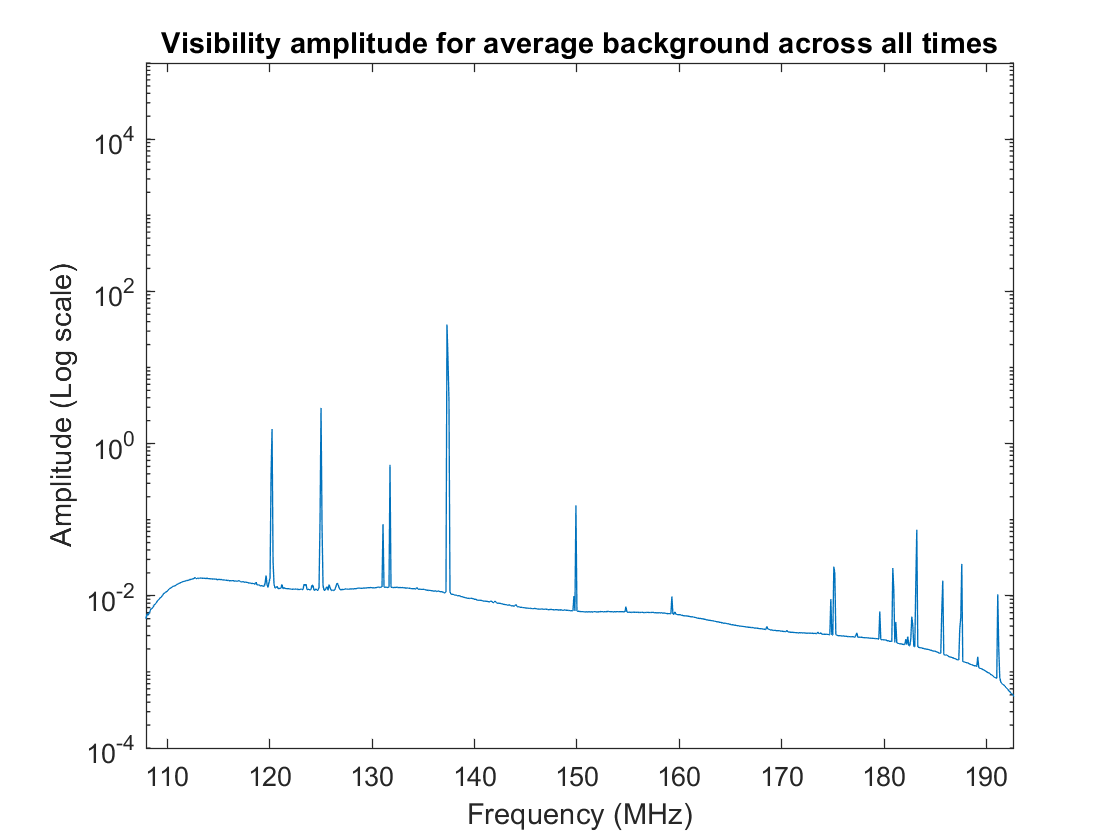

clf;
semilogy(freq_array ./ 1e6, amplitude_avg)
xlabel('Frequency (MHz)');
ylabel('Amplitude (Log scale)')
xlim([107.9 192.7])
ylim([1e-4 1e5])
title(['Visibility amplitude for average background across all times'])

The background does not appear to be constant across the range of frequencies. In fact, the background seems to have a higher amplitude for lower frequencies than for higher frequencies.

We can perform a **jacknife test** to confirm or reject this hypothesis. By comparing the visibility data from one low-frequency region to one high-frequency region, one would expect that, if these two regions have different levels of background, the histogram of the *difference of these sets of data* should be relatively large in amplitude (i.e. much more than or much less than 0 counts in each bin.)

First, we need to define two frequency ranges in our data above that appear to have a constant level of background. The two regions we will be focusing on are $127\;\mathrm{MHz}<f<130\;\mathrm{MHz}$ and $151\;\textrm{MHz}<f<154\;\textrm{MHz}$. Ignoring the apparent spikes in the data, which we will omit in our analysis, these regions appear to have a relatively constant background.

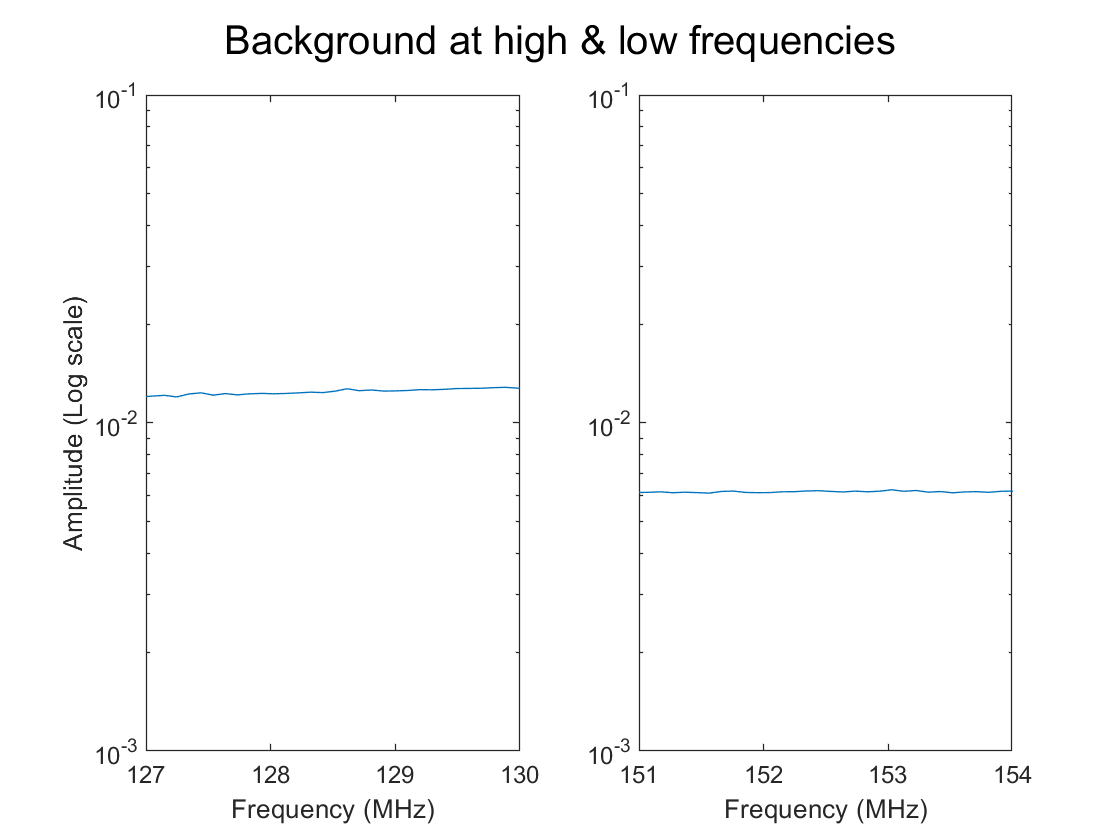

%region bounds in MHz
f1i = 127;
f1f = 130;
f2i = 151;
f2f = 154;

clf;
sgtitle('Background at high & low frequencies')
subplot(1, 2, 1)
semilogy(freq_array ./ 1e6, amplitude_avg)
xlabel('Frequency (MHz)');
ylabel('Amplitude (Log scale)')
xlim([f1i f1f])
ylim([0.001 0.1])

subplot(1, 2, 2)
semilogy(freq_array ./ 1e6, amplitude_avg .* (amplitude_avg(1:1024) < 0.03))
xlabel('Frequency (MHz)');
xlim([f2i f2f])
ylim([0.001 0.1])

Just by looking at these two plot side-by-side, which have been plotted on the same y-axis, we can anticipate that the low-frequency region has a higher background than the high-frequency region. By histogramming the data from each of these regions, we can see if the data is statistically different between regions or not.

%find indices of closest frequencies to this range in our data
[~, f1iind] = min(abs(freq_array - f1i * 1e6))

f1iind = 277

[~, f1find] = min(abs(freq_array - f1f * 1e6))

f1find = 308

[~, f2iind] = min(abs(freq_array - f2i * 1e6))

f2iind = 523

[~, f2find] = min(abs(freq_array - f2f * 1e6))

f2find = 554

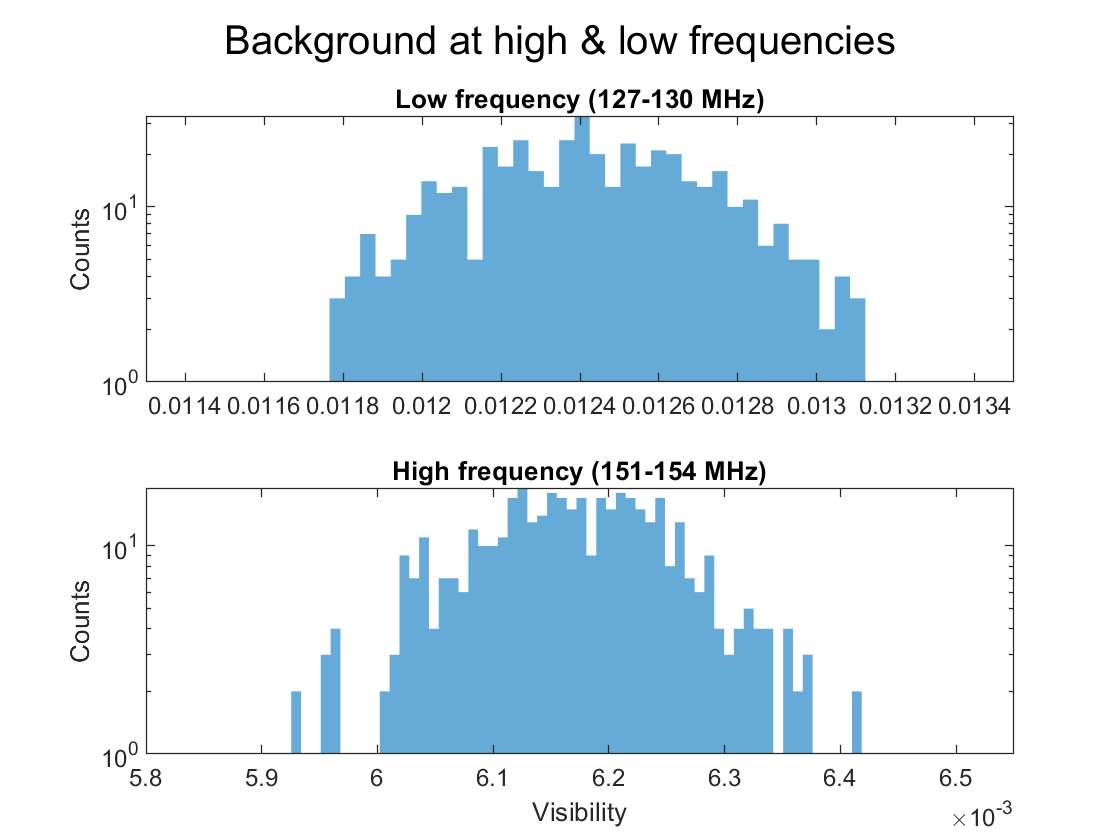

r1_data = averages(f1iind:f1find, :);
r2_data = averages(f2iind:f2find, :);

maxval = 0.03;
nbins = 75;
clf;

subplot(2, 1, 1)
h1 = histogram(r1_data, nbins, 'EdgeColor', 'none');
h1data = h1.Values;
set(gca, 'YScale', 'log')
ylabel('Counts');
title('Low frequency (127-130 MHz)')
xlim([0.0113 0.0135])

subplot(2, 1, 2)
h2 = histogram(r2_data, nbins, 'EdgeColor', 'none');
h2data = h2.Values;
set(gca, 'YScale', 'log')
xlabel('Visibility');
ylabel('Counts');
title('High frequency (151-154 MHz)')
xlim([0.0058 0.00655])
sgtitle('Background at high & low frequencies')

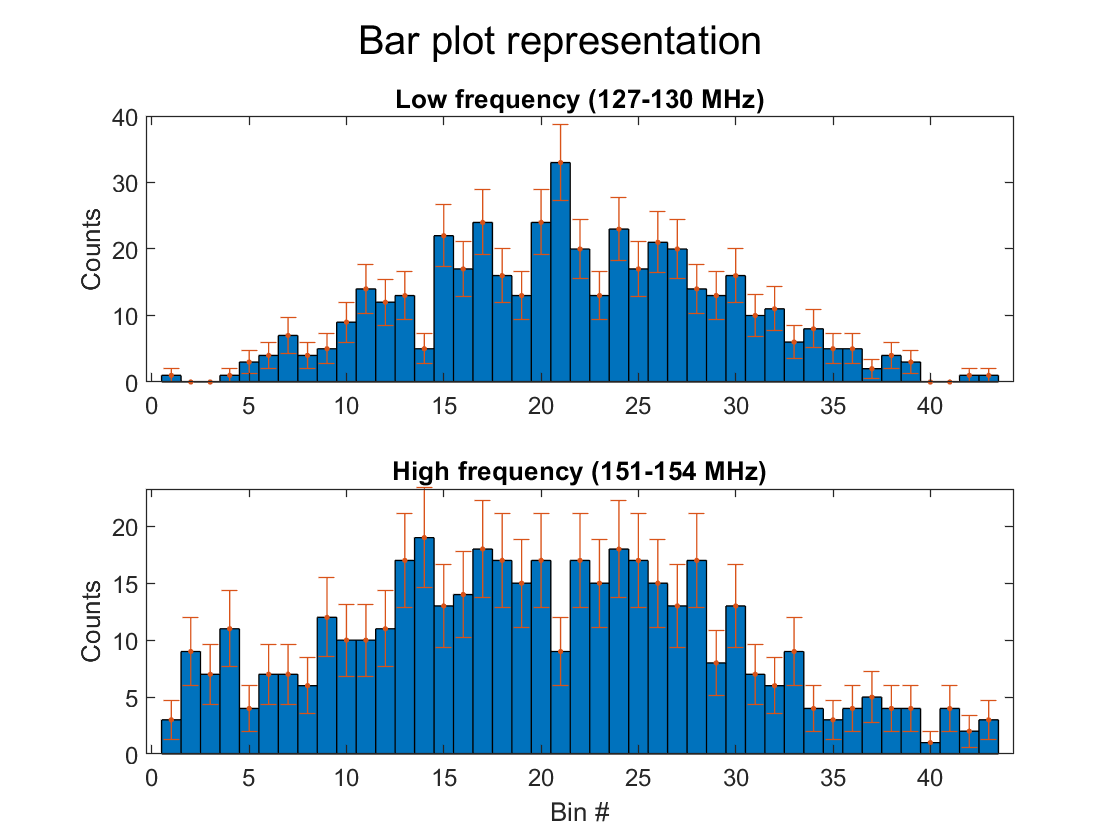

%Manually find the bin edges which correspond to the main bulk of the histogram
b1 = h1data(1:43);
b2 = h2data(22:64);

%Convert histograms to bar charts - this makes it easier to visualize and code the
%difference plot in the next step
clf;
subplot(2, 1, 1)
bar(b1, 1), hold on;
errorbar(b1, sqrt(abs(b1)), '.')
legend('Histogram data', 'Error bars')
ylabel('Counts')
title('Low frequency (127-130 MHz)')
subplot(2, 1, 2)
bar(b2, 1), hold on;
errorbar(b2, sqrt(abs(b2)), '.')
xlabel('Bin #');
ylabel('Counts')
title('High frequency (151-154 MHz)')
legend('Histogram data', 'Error bars')
sgtitle('Bar plot representation')

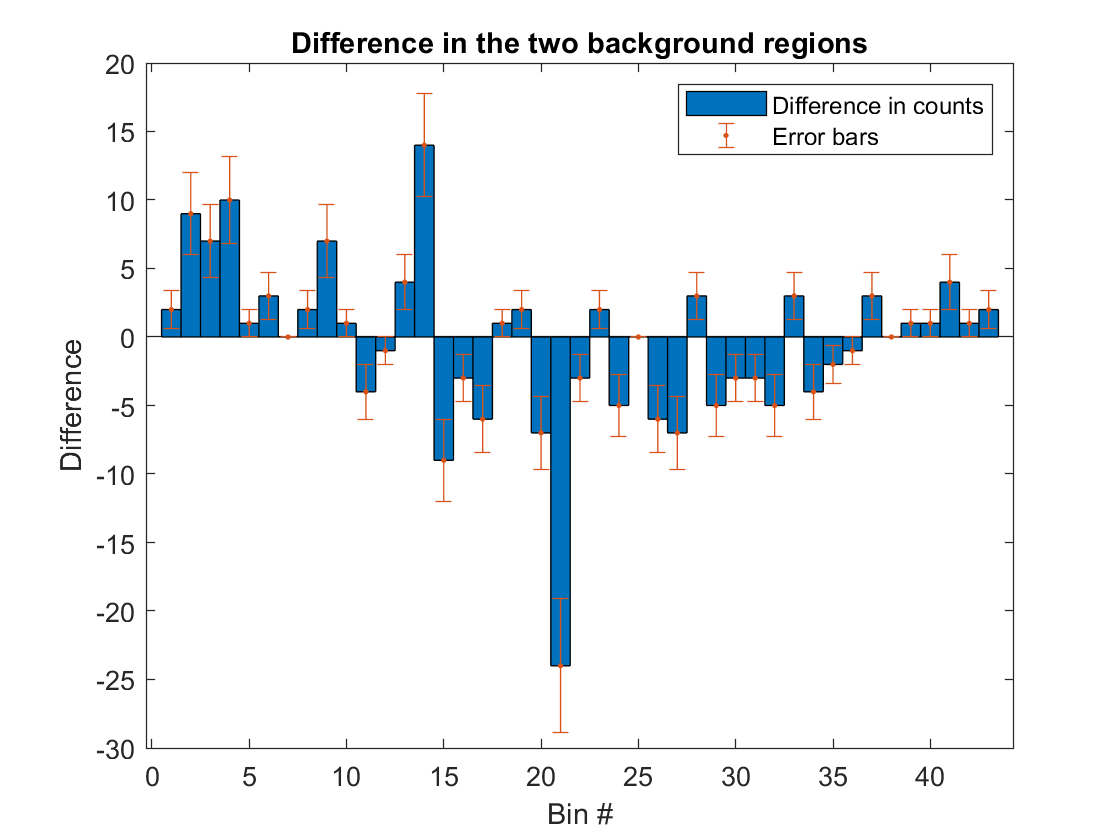

diff_hist = b2-b1;
clf;
bar(diff_hist, 1), hold on;
errorbar(diff_hist, sqrt(abs(diff_hist)), '.')
xlabel('Bin #');
ylabel('Difference');
legend('Difference in counts', 'Error bars')
title('Difference in the two background regions')

If the data from these two regions were similar enough, the difference between the two regions would be close to zero. We would be able to say that the data sets are essentially statistically identical if the error bars were to overlap the x-axis. However, we do not observe this - instead, the difference in the background between the two regions is so great that the difference in the number of counts is much, much larger than the width of the error bars. Our jackknife test proves our hypothesis that the background from these two regions is** statistically different**. Therefore, we can conclude that the background distribution does depend on frequency.

Given this conclusion, in order to analyze a signal within our background, we need to only look at a certain range of frequencies in which the background remains relatively constant. As shown earlier, one cannot accurately model the entire range of data with any one statistical distribution, so we must resort to focusing on one specific region in which a signal may lie in.

In order to propery analyze data for signals, we must make two cuts to the data:

- Cut the data such that you only focus on a specific range of frequencies in which the background is relatively constant. This will make sure the frequency dependence of the background distribution does not affect the results.

- Omit any data where the visibility amplitude is much larger than the average background. This will remove the spikes in the background corresponding to satellite communication or broadcasting, as shown above.

This process is best represented by the histograms we made for the jackknife test, where we focus on a very small range of frequencies and remove all data with an amplitude over a certain value.

clf;
subplot(2, 1, 1)
h1 = histogram(r1_data, nbins, 'EdgeColor', 'none');
set(gca, 'YScale', 'log')
ylabel('Counts');
title('Low frequency (127-130 MHz)')
xlim([0.0113 0.0135])

subplot(2, 1, 2)
h2 = histogram(r2_data, nbins, 'EdgeColor', 'none');
h2data = h2.Values;
set(gca, 'YScale', 'log')
xlabel('Visibility');
ylabel('Counts');
title('High frequency (151-154 MHz)')
xlim([0.0058 0.00655])

sgtitle('Background at high & low frequencies')

As we expand our range of frequencies in our cut, or as we increase the threshold which we cut off high signals from, the significance of a possible signal becomes smaller and smaller as we include more noise (background) in our analysis.

function imgdata = bl2img(baseline)
%Given a specific pair of antennas (X, Y), or just a baseline N, outputs
%data which can be passed to imagesc()
if isscalar(baseline)
    bl = baseline;
else
    bl = find(ismember(baselines, baseline, "rows"));
end

baseline_waterfall_data = visdata_mag(:, :, :, bl:1378:end);
imgdata = squeeze(baseline_waterfall_data)';
end